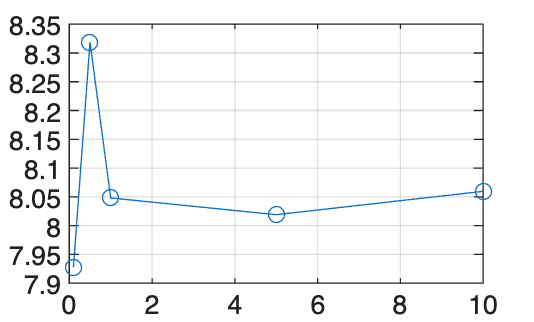

steps = [1000 5000 10000 50000 100000];

for i = 1:length(steps)

    N = steps(i);

    Z = randn(N,1);

    ST = S0*exp((r-0.5*sigma^2)*T + sigma*sqrt(T).*Z);

    payoff = max(ST-K,0);

    price(i) = exp(-r*T)*mean(payoff);

end

plot(steps,price,'-o')
xlabel('Number of Simulations')
ylabel('Monte Carlo Price')
grid on